# **Tesis: Identifikasi Sistem**

**M. Alifsyah Putra Nasution (23221086)**

clearvars
close all
clc

## Identifikasi Sistem dengan Model NARX-NN (Putri dkk., 2021)

NARX-NN Menggunakan FNN dengan SGD

% style = 1;   %style pilih 1 atau 2 (1 jika generate data random, 2 jika pakai data asli misalnya dari file .xlsx)
% 
% pilihan = 2;   %pilihan pilih 1 atau 2 (1 jika pakai fungsi awgn, 2 jika pakai fungsi normrnd)(khusus style == 1)
% var = 0.05;   %variance noise (khusus style == 1)
% 
% jenis_data = 3; %jenis_data pilih 1, 2, 3, atau 4 (1 jika pakai data asli dari plant sistem kolom distilasi, 2 jika pakai data random dengan var 0,001, 3 jika pakai data random dengan var 0,05, 4 jika pakai data yang lain)(khusus style == 2)

style = 2;   %style pilih 1 atau 2 (1 jika generate data random, 2 jika pakai data asli misalnya dari file .xlsx)

pilihan = 2;   %pilihan pilih 1 atau 2 (1 jika pakai fungsi awgn, 2 jika pakai fungsi normrnd)(khusus style == 1)
var = 0;   %variance noise (khusus style == 1)

jenis_data = 1; %jenis_data pilih 1, 2, 3, atau 4 (1 jika pakai data asli dari plant sistem kolom distilasi, 2 jika pakai data random dengan var 0,001, 3 jika pakai data random dengan var 0,05, 4 jika pakai data yang lain)(khusus style == 2)

limit = 1; %limit pilih 1 atau 2 (1 jika ylim ingin dibatasi secara manual, 2 jika ylim ingin otomatis)(khusus style == 2 && jenis_data == 1)
% meta kombinasi: 22011

if style == 1

%Example Lain
%parameter-parameter sistem dengan model NARX yang ingin diidentifikasi
% ini model NARMA yang saya ambil dari estimasi MATLAB itu sendiri untuk
% Example 3 (Tutunji, 2016)
a = [0.5564; -0.0478; 0.0451; 0.0823];
b = [-0.0313; 0.0348; -0.1423];
A = [0.2634 -0.0269 -0.0632 0.0293;
     -0.0269 -0.0102 0.0043 -0.0150;
     -0.0632 0.0043 -0.0210 -0.0115;
     0.0293 -0.0150 -0.0115 -0.0080];
B = [-0.0574 -0.0070 -0.0254;
     -0.0070 -0.0267 0.0067;
     -0.0254 0.0067 0.0203];
C = [0.2591 -0.0065 -0.1545;
     -0.0487 -0.0360 0.0250;
     0.0605 -0.0162 0.0288;
     0.0169 -0.0354 -0.0093];

orde1 = size(b,1);   %tergantung size-nya b idealnya karna terkait jumlah y yang di-delayed
n1 = size(b,1);
m1 = size(a,1)-1;

## Time Span

Ts = 1;
k_akh = 299;
t = (0:Ts:k_akh).';

%create input values
for i=1:length(t)
    u_temp(i,1)=rand(1); % data input temp (ditarik dari Uniformly distributed random numbers dalam interval (0-1))
end 

for i=1:length(t)
    u_tes_temp(i,1)=rand(1); % data input tes temp (ditarik dari Uniformly distributed random numbers dalam interval (0-1))
end 

%untuk NARX-NN
for i=1:m1
    u(i,1)=0; % data input
    u_tes(i,1)=0;
    u_step(i,1)=0;
    u_imp(i,1)=0;
    u_sin(i,1)=0;
end 
for i=1:length(t)
    u(i+3,1)=u_temp(i,1); % data input
end 

for i=1:length(t)
    u_tes(i+3,1)=u_tes_temp(i,1); % data input tes
end

%create input unit step function manually
% for i=1:length(t)
%     u_step(i,1)=1; % data input step
% end 
for i=1:length(t)
    u_step(i+3,1)=1; % data input step
end 

for i=1:length(t)
    if i==1
        u_imp(i+3,:) = 1;
    else
    u_imp(i+3,1)=0; % data input impulse
    end 
end

for i=1:length(t)
    u_sin(i+3,1)=u_sin(i+2,1)+0.1; % data input step
end 

tt = (0:Ts:length(u)-1).';
figure,
plot(tt,u,'r');
legend('u','location','northeast');
title('Input from Learning Data');

figure,
plot(tt,u_tes,'r');
legend('u','location','northeast');
title('Input from Test Data');

% %create output values
for i=1:n1
    y(i,1)=0; % data output
    y_tes(i,1)=0;
    y_step(i,1)=0;
    y_imp(i,1)=0;
    y_sin(i,1)=0;
end

for k=1:length(t)
    for i=0:m1
    uu(i+1,k) = u(k+m1-i,:);
    end
    for j=1:n1
    yy(j,k) = y(k+n1-j,:);
    end

    y(k+n1,:) = a.'*uu(:,k) + b.'*yy(:,k) + (uu(:,k)).'*A*uu(:,k) + (yy(:,k)).'*B*yy(:,k) + (uu(:,k)).'*C*yy(:,k);

end

for k=1:length(t)
    for i=0:m1
    uu_tes(i+1,k) = u_tes(k+m1-i,:);
    end
    for j=1:n1
    yy_tes(j,k) = y_tes(k+n1-j,:);
    end

    y_tes(k+n1,:) = a.'*uu_tes(:,k) + b.'*yy_tes(:,k) + (uu_tes(:,k)).'*A*uu_tes(:,k) + (yy_tes(:,k)).'*B*yy_tes(:,k) + (uu_tes(:,k)).'*C*yy_tes(:,k);

end

%LANJUT YANG STEP DAN IMPULSE

for k=1:length(t)
    for i=0:m1
    uu_step(i+1,k) = u_step(k+m1-i,:);
    end
    for j=1:n1
    yy_step(j,k) = y_step(k+n1-j,:);
    end

    y_step(k+n1,:) = a.'*uu_step(:,k) + b.'*yy_step(:,k) + (uu_step(:,k)).'*A*uu_step(:,k) + (yy_step(:,k)).'*B*yy_step(:,k) + (uu_step(:,k)).'*C*yy_step(:,k);

end

for k=1:length(t)
    for i=0:m1
    uu_imp(i+1,k) = u_imp(k+m1-i,:);
    end
    for j=1:n1
    yy_imp(j,k) = y_imp(k+n1-j,:);
    end

    y_imp(k+n1,:) = a.'*uu_imp(:,k) + b.'*yy_imp(:,k) + (uu_imp(:,k)).'*A*uu_imp(:,k) + (yy_imp(:,k)).'*B*yy_imp(:,k) + (uu_imp(:,k)).'*C*yy_imp(:,k);

end


%with measurement noise 
if pilihan == 1
    %dengan additive, white, and gaussian noise
    %snr makin besar -> noise makan kecil
%     snr = 100;   %jika ingin ys=y maka snr->infinity (snr 100 dB aja noisenya seperti sudah tidak ada)
%     snr = 1;   %noisenya sudah termasuk parah ini
%     snr = 20;
%     snr = 30;
    snr = -10*log10(var);

    [ys,var2] = awgn(y,snr);
    ys_tes = awgn(y_tes,snr);
    ys_step = awgn(y_step,snr);
    ys_imp = awgn(y_imp,snr);
    
    for i=1:n1
        ys(i,1)=0;
        ys_tes(i,1)=0;
        ys_step(i,1)=0;
        ys_imp(i,1)=0;
    end

elseif pilihan == 2
    %ini juga hasilkan noise yang bersifat additive (karna ditambah), white
    %(karna pakai for), dan gaussian (karna pakai fungsi normrnd). Sedangkan, variance
    %sudah ditentukan di atas
    mu = 0; %mean
%     var = 0.01; %variance
%     var = 0.001; %variance
    sd = sqrt(var); %deviation standard
    
    for i=1:length(y)
        ys(i,1) = y(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:length(y)
        ys_tes(i,1) = y_tes(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:length(y)
        ys_step(i,1) = y_step(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:length(y)
        ys_imp(i,1) = y_imp(i,1) + normrnd(mu,sd); % noise ditarik dari normally distributed random numbers dengan mean mu 0 dan variance var (sd^2) atau deviation standard sd tertentu
    end
    
    for i=1:n1
        ys(i,1)=0;
        ys_tes(i,1)=0;
        ys_step(i,1)=0;
        ys_imp(i,1)=0;
    end
    
end


figure,
plot(tt,ys,'r'); hold on
plot(tt,y,'g');
legend('ys','y','location','northeast');
title('Output Response from Learning Data');

figure,
plot(tt,ys_tes,'r'); hold on
plot(tt,y_tes,'g');
legend('ys','y','location','northeast');
title('Output Response from Test Data');

figure,
plot(tt,ys_step,'r'); hold on
plot(tt,y_step,'g');
legend('ys','y','location','northeast');
title('Step Response');

figure,
plot(tt,ys_imp,'r'); hold on
plot(tt,y_imp,'g');
legend('ys','y','location','northeast');
title('Impulse Response');

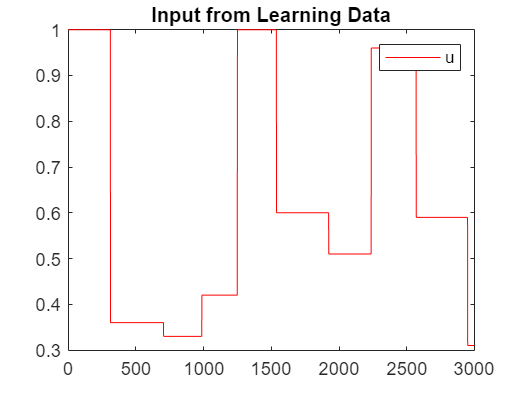

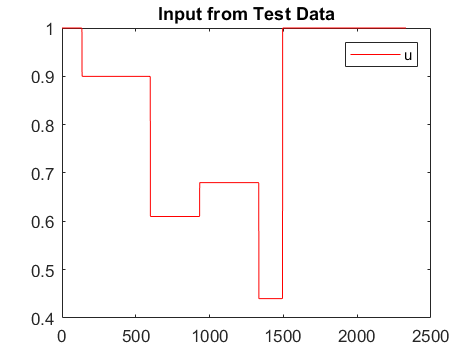

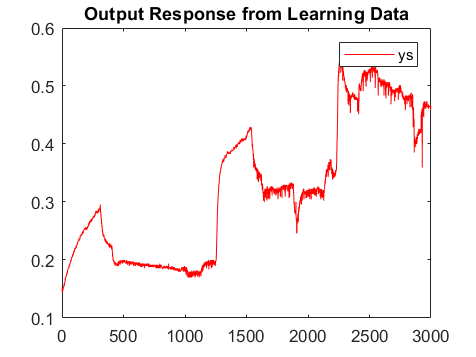

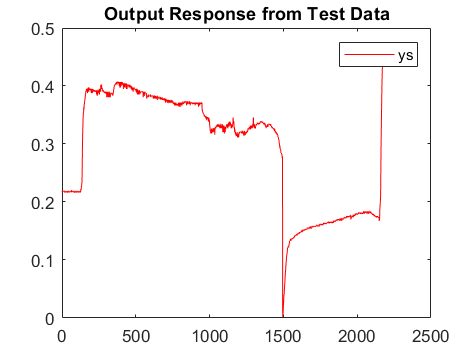

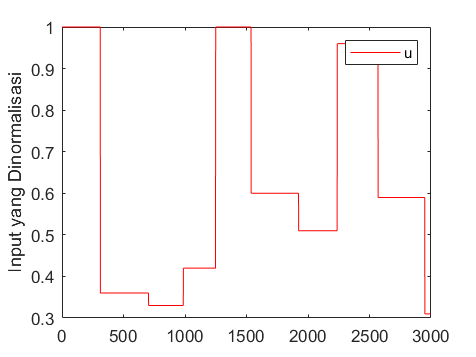

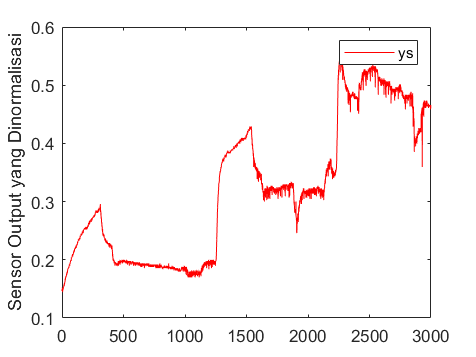

elseif style == 2

if jenis_data == 1
% data = readmatrix('asli_1_data_learning_20230331(data1).xlsx');
data = readmatrix('asli1_datatraining_31.xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

% data = readmatrix('asli_2_data_test_20230329(data2).xlsx');
data = readmatrix('asli2_datatesting_14.xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

elseif jenis_data == 2
data = readmatrix('1_data_learning(data1).xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

data = readmatrix('2_data_test(data2).xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

elseif jenis_data == 3
data = readmatrix('3_data_learning(data3).xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

data = readmatrix('4_data_test(data4).xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

elseif jenis_data == 4
data = readmatrix('3_data_learning(data3).xlsx');
u = data(:,1);
ys = data(:,2);
y = ys; 
%y = data(:,3);

data = readmatrix('4_data_test(data4).xlsx');
u_tes = data(:,1);
ys_tes = data(:,2);
y_tes = ys_tes;
%y_tes = data(:,3);

end


Ts = 1;
tt = (0:Ts:length(u)-1).';
figure,
plot(tt,u,'r');
legend('u','location','northeast');
title('Input from Learning Data');

clear tt;
tt = (0:Ts:length(u_tes)-1).';
figure,
plot(tt,u_tes,'r');
legend('u','location','northeast');
title('Input from Test Data');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
plot(tt,ys,'r'); 
legend('ys','location','northeast');
title('Output Response from Learning Data');

clear tt;
tt = (0:Ts:length(ys_tes)-1).';
figure,
plot(tt,ys_tes,'r'); 
legend('ys','location','northeast');
title('Output Response from Test Data');
end


Ts = 1;
tt = (0:Ts:length(u)-1).';
figure,
plot(tt,u,'r');
legend('u','location','northeast');
ylabel('Input yang Dinormalisasi');
% title('Input from Learning Data');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
plot(tt,ys,'r'); 
legend('ys','location','northeast');
ylabel('Sensor Output yang Dinormalisasi');
% title('Output Response from Learning Data');

## **Learning Algorithm (Inisialisasi Parameter)**

%parameter neural network dengan 1 input layer, 1 hidden layer, dan
%1 output layer, jadi jumlah layer 3 misalnya
if style == 1
orde = orde1; %orde estimated transfer function
elseif style == 2
% orde = 3; %orde estimated transfer function
orde = 3; %orde estimated transfer function
end

% H = 3; %jumlah hidden nodes
H = 5; %jumlah hidden nodes
n = orde; %jumlah delayed output
m = n; %jumlah delayed input
%lay = 3; %jumlah layer (1 input layer, 1 output layer, dan (lay-2) hidden layer)

banyak_epoch = 15; %banyak epoch
%banyak_epoch = 150; %banyak epoch

%initialize network weights randomly (rentangnya dari -1 sampai 1, sedangkan fungsi rand itu rentangnya 0-1 ditarik dari uniform distribution)
aaa = -1;
bbb = 1;
w = (bbb-aaa).*rand(H,orde+1)+aaa;
v = (bbb-aaa).*rand(H,orde)+aaa;
wout = (bbb-aaa).*rand(H,1)+aaa;

weights(:,:,1,1) = [w v wout];

%weights(:,:,1,1) = readmatrix('weights_awal1.xlsx');

weights(:,:,1,1) = 0.05*ones(H,m+1+n+1);

weights_awal = weights(:,:,1,1)

weights_awal =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500




sizeP = size(weights,1)*size(weights,2);


%inisialisasi parameter untuk standard backpropagation algorithm
%alpha = 1/1e-06; %learning rate   %TERNYATA UBAH2 LEARNING RATE NGARUH, PAS 1/1e-06 UNTUK MODEL YG ORDE 3 INI DIA WEIGHTNYA JADI NaN, tidak konvergen
alpha = 0.75;


%inisialisasi parameter-parameter untuk algoritma EKF 
P0_awal = 50*eye(sizeP);   %P0 yang sebenarnya
P0 = P0_awal;
Qekf = 1e-6*eye(sizeP);
% Rekf = 1e-6;   %dia jadi gak stabil hasilnya, MSE nya juga infinity
if style == 1
Rekf = var;
end
Rekf = 1;
Rekf = 1/alpha;

## Learning Algorithm

%TDL Block (ini untuk nyusun vektor FNN desired inputs (fitur-fitur FNN) u_d(k))
yd = y;   %hanya berlaku untuk style == 1 jika ingin y yang digunakan untuk training
yd = ys;   %yang digunakan untuk training

for k=1:length(yd)

    for j=0:m
        jj=k-j;
        if jj<=0
            uuu(j+1,:) = 0;
        else
            uuu(j+1,:) = u(jj,:);
        end
    end

    for j=1:n
        jj=k-j;
        if jj<=0
            yyy(j,:) = 0;
        else
            yyy(j,:) = yd(jj,:);
        end
    end

L(:,k)=[uuu;
        yyy];   %input ke feedforward neural network (u_d(k))
end

%Jadi, 1 epoch itu setelah 303 iterasi (instance-by-instance) misalnya!

## **Feedforward Neural Network**

%dengan hyperbolic tangent with alpha = 1 activation function
%for hidden layer dan linear activation function for output layer
for h=1:H
    der1(:,h)=0.5;
end
for h=1:H
    der2(:,h)=0.1;   %dibuat aja karna kalo beneran dimasukin 0 hasilnya 0 turunan ke-2 si tangent hyperbolic
end

for epoch=1:banyak_epoch   %tentukan jumlah epoch
    for k=1:length(yd)
        
        a_est(:,k,epoch) = zeros(m+1,1);
        for h=1:H
        a_est(:,k,epoch) = a_est(:,k,epoch) + weights(h,(1+orde+orde+1),k,epoch)*der1(:,h)*weights(h,1:(1+orde),k,epoch).';
        end

        b_est(:,k,epoch) = zeros(n,1);
        for h=1:H
        b_est(:,k,epoch) = b_est(:,k,epoch) + weights(h,(1+orde+orde+1),k,epoch)*der1(:,h)*weights(h,(1+orde+1):(1+orde+orde),k,epoch).';
        end

        A_est(:,:,k,epoch) = zeros(m+1,m+1);
        for h=1:H
        A_est(:,:,k,epoch) = A_est(:,:,k,epoch) + weights(h,(1+orde+orde+1),k,epoch)*der2(:,h)*weights(h,1:(1+orde),k,epoch).'*weights(h,1:(1+orde),k,epoch);
        end

        B_est(:,:,k,epoch) = zeros(n,n);
        for h=1:H
        B_est(:,:,k,epoch) = B_est(:,:,k,epoch) + weights(h,(1+orde+orde+1),k,epoch)*der2(:,h)*weights(h,(1+orde+1):(1+orde+orde),k,epoch).'*weights(h,(1+orde+1):(1+orde+orde),k,epoch);
        end

        C_est(:,:,k,epoch) = zeros(m+1,n);
        for h=1:H
        C_est(:,:,k,epoch) = C_est(:,:,k,epoch) + 2*(weights(h,(1+orde+orde+1),k,epoch)*der2(:,h)*weights(h,1:(1+orde),k,epoch).'*weights(h,(1+orde+1):(1+orde+orde),k,epoch));
        end

        y_net(k,:,epoch) = (a_est(:,k,epoch)).'*L(1:(1+orde),k) + (b_est(:,k,epoch)).'*L((1+orde+1):(1+orde+orde),k);
        y_net(k,:,epoch) = y_net(k,:,epoch) + L(1:(1+orde),k).'*A_est(:,:,k,epoch)*L(1:(1+orde),k);
        y_net(k,:,epoch) = y_net(k,:,epoch) + L((1+orde+1):(1+orde+orde),k).'*B_est(:,:,k,epoch)*L((1+orde+1):(1+orde+orde),k);
        y_net(k,:,epoch) = y_net(k,:,epoch) + L(1:(1+orde),k).'*C_est(:,:,k,epoch)*L((1+orde+1):(1+orde+orde),k);
        
        if style == 1
        e(k,:,epoch) = y(k,:)-y_net(k,:,epoch);
        end
        es(k,:,epoch) = ys(k,:)-y_net(k,:,epoch);

        ed(k,:,epoch) = (yd(k,:)-y_net(k,:,epoch));
        
        if style == 1
        mse_e(k,:,epoch) = mse(e(k,:,epoch));
        end
        mse_es(k,:,epoch) = mse(es(k,:,epoch));


        %PERHITUNGAN FEEDFORWARD PEMBANDING
        for h=1:H
        net(h,k,epoch) = weights(h,1:(1+orde),k,epoch)*L(1:(1+orde),k) + weights(h,(1+orde+1):(1+orde+orde),k,epoch)*L((1+orde+1):(1+orde+orde),k);   
        %z itu output hidden layer (setelah net diterapkan activation function)
        z(h,k,epoch) = der1(:,h)*net(h,k,epoch) + der2(:,h)*(net(h,k,epoch))^2;   %bedanya di sini aja sama yg neural network tutunji untuk yg linier
        end
        y_net2(k,:,epoch) = weights(:,(1+orde+orde+1),k,epoch).'*z(:,k,epoch);
        
        if style == 1
        e2(k,:,epoch) = y(k,:)-y_net2(k,:,epoch);
        end
        es2(k,:,epoch) = ys(k,:)-y_net2(k,:,epoch);


        %Learning Algorithm
        %Menggunakan algoritma standard backpropagation dengan 
        %Steepest (Gradient) Descent (SGD)
        %1) Hitung Sum Squared Error (SSE) dikali 1/2 per pasangan input dan
        %target output dalam 1 kali perhitungan feedforward.
        %Ini sebagai fungsi objektif atau indeks performa yang ingin diminimumkan tapi bukan
        %total seluruh data set, hanya pair per pasangan input dan output.
        if style == 1
        SSE(k,:,epoch) = (1/2)*sse(e(k,:,epoch));
        SSE2(k,:,epoch) = (1/2)*sse(e2(k,:,epoch));
        end

        %2) Update bobot-bobot
        %di output layer menggunakan linear activation function f(x) = x ->
        %f_dot(x) = 1

        %untuk output layer (wouth)
        der_wouth(:,k,epoch) = -1*ed(k,:,epoch)*z(:,k,epoch);

        %update wouth
        weights(:,(1+orde+orde+1),k+1,epoch) = weights(:,(1+orde+orde+1),k,epoch) - alpha*der_wouth(:,k,epoch);

        %untuk wih dan vjh
        %untuk wih
        der_wih(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(der1 + 2*der2.*net(:,k,epoch).').'*L(1:(1+orde),k).';   %gunakan wouth yg sudah diupdate

        %update wih
        weights(:,1:(1+orde),k+1,epoch) = weights(:,1:(1+orde),k,epoch) - alpha*der_wih(:,:,k,epoch);

        %untuk vjh
        der_vjh(:,:,k,epoch) = -1*ed(k,:,epoch)*weights(:,(1+orde+orde+1),k+1,epoch).*(der1 + 2*der2.*net(:,k,epoch).').'*L((1+orde+1):(1+orde+orde),k).';   %gunakan wouth yg sudah diupdate

        %update vjh
        weights(:,(1+orde+1):(1+orde+orde),k+1,epoch) = weights(:,(1+orde+1):(1+orde+orde),k,epoch) - alpha*der_vjh(:,:,k,epoch);

    end
    weights(:,:,1,epoch+1) = weights(:,:,size(weights,3),epoch);
end

weights(:,:,1,epoch+1)

ans =     0.0835    0.0081   -0.0417    0.0514    0.3345    0.3706    0.4113    0.3054
    0.0835    0.0081   -0.0417    0.0514    0.3345    0.3706    0.4113    0.3054
    0.0835    0.0081   -0.0417    0.0514    0.3345    0.3706    0.4113    0.3054
    0.0835    0.0081   -0.0417    0.0514    0.3345    0.3706    0.4113    0.3054
    0.0835    0.0081   -0.0417    0.0514    0.3345    0.3706    0.4113    0.3054


## **Estimasi Parameter NARX**

%estimasi parameter NARX
a_est1 = zeros(m+1,1);
for h=1:H
a_est1 = a_est1 + weights(h,(1+orde+orde+1),size(weights,3),epoch)*der1(:,h)*weights(h,1:(1+orde),size(weights,3),epoch).';
end

b_est1 = zeros(n,1);
for h=1:H
b_est1 = b_est1 + weights(h,(1+orde+orde+1),size(weights,3),epoch)*der1(:,h)*weights(h,(1+orde+1):(1+orde+orde),size(weights,3),epoch).';
end

A_est1 = zeros(m+1,m+1);
for h=1:H
A_est1 = A_est1 + weights(h,(1+orde+orde+1),size(weights,3),epoch)*der2(:,h)*weights(h,1:(1+orde),size(weights,3),epoch).'*weights(h,1:(1+orde),size(weights,3),epoch);
end

B_est1 = zeros(n,n);
for h=1:H
B_est1 = B_est1 + weights(h,(1+orde+orde+1),size(weights,3),epoch)*der2(:,h)*weights(h,(1+orde+1):(1+orde+orde),size(weights,3),epoch).'*weights(h,(1+orde+1):(1+orde+orde),size(weights,3),epoch);
end

C_est1 = zeros(m+1,n);
for h=1:H
C_est1 = C_est1 + 2*(weights(h,(1+orde+orde+1),size(weights,3),epoch)*der2(:,h)*weights(h,1:(1+orde),size(weights,3),epoch).'*weights(h,(1+orde+1):(1+orde+orde),size(weights,3),epoch));
end

if style == 1
a
a_est1
a_est0 = a_est(:,1,1)

b
b_est1
b_est0 = b_est(:,1,1)

A
A_est1
A_est0 = A_est(:,:,1,1)

B
B_est1
B_est0 = B_est(:,:,1,1)

C
C_est1
C_est0 = C_est(:,:,1,1)

% a
% a_est1
% 
% b
% b_est1
% 
% A
% A_est1
% 
% B
% B_est1
% 
% C
% C_est1

elseif style == 2
a_est1
a_est0 = a_est(:,1,1)

b_est1
b_est0 = b_est(:,1,1)

A_est1
A_est0 = A_est(:,:,1,1)

B_est1
B_est0 = B_est(:,:,1,1)

C_est1
C_est0 = C_est(:,:,1,1)

end

a_est1 =     0.0638
    0.0062
   -0.0318
    0.0392


a_est0 =     0.0063
    0.0063
    0.0063
    0.0063


b_est1 =     0.2554
    0.2830
    0.3140


b_est0 =     0.0063
    0.0063
    0.0063


A_est1 =     0.0011    0.0001   -0.0005    0.0007
    0.0001    0.0000   -0.0001    0.0001
   -0.0005   -0.0001    0.0003   -0.0003
    0.0007    0.0001   -0.0003    0.0004


A_est0 = 1.0e-04 *

    0.6250    0.6250    0.6250    0.6250
    0.6250    0.6250    0.6250    0.6250
    0.6250    0.6250    0.6250    0.6250
    0.6250    0.6250    0.6250    0.6250


B_est1 =     0.0171    0.0189    0.0210
    0.0189    0.0210    0.0233
    0.0210    0.0233    0.0258


B_est0 = 1.0e-04 *

    0.6250    0.6250    0.6250
    0.6250    0.6250    0.6250
    0.6250    0.6250    0.6250


C_est1 =     0.0085    0.0095    0.0105
    0.0008    0.0009    0.0010
   -0.0043   -0.0047   -0.0052
    0.0053    0.0058    0.0065


C_est0 = 1.0e-03 *

    0.1250    0.1250    0.1250
    0.1250    0.1250    0.1250
    0.1250    0.1250    0.1250
    0.1250    0.1250    0.1250


%
if style == 1
for i=1:n
    y_est(i,1)=0; % data output
    y_tes_est(i,1)=0;
    y_step_est(i,1)=0;
    y_imp_est(i,1)=0;
    y_sin_est(i,1)=0;
end

for k=1:(length(u)-n)
    for i=0:m
    uu(i+1,k) = u(k+m-i,:);
    end
    for j=1:n
    yy(j,k) = y_est(k+n-j,:);
    end

    y_est(k+n,:) = a_est1.'*uu(:,k) + b_est1.'*yy(:,k) + (uu(:,k)).'*A_est1*uu(:,k) + (yy(:,k)).'*B_est1*yy(:,k) + (uu(:,k)).'*C_est1*yy(:,k);

end

for k=1:(length(u_tes)-n)
    for i=0:m
    uu_tes(i+1,k) = u_tes(k+m-i,:);
    end
    for j=1:n
    yy_tes(j,k) = y_tes_est(k+n-j,:);
    end

    y_tes_est(k+n,:) = a_est1.'*uu_tes(:,k) + b_est1.'*yy_tes(:,k) + (uu_tes(:,k)).'*A_est1*uu_tes(:,k) + (yy_tes(:,k)).'*B_est1*yy_tes(:,k) + (uu_tes(:,k)).'*C_est1*yy_tes(:,k);

end

for k=1:(length(u_step)-n)
    for i=0:m
    uu_step(i+1,k) = u_step(k+m-i,:);
    end
    for j=1:n
    yy_step(j,k) = y_step_est(k+n-j,:);
    end

    y_step_est(k+n,:) = a_est1.'*uu_step(:,k) + b_est1.'*yy_step(:,k) + (uu_step(:,k)).'*A_est1*uu_step(:,k) + (yy_step(:,k)).'*B_est1*yy_step(:,k) + (uu_step(:,k)).'*C_est1*yy_step(:,k);

end

for k=1:(length(u_imp)-n)
    for i=0:m
    uu_imp(i+1,k) = u_imp(k+m-i,:);
    end
    for j=1:n
    yy_imp(j,k) = y_imp_est(k+n-j,:);
    end

    y_imp_est(k+n,:) = a_est1.'*uu_imp(:,k) + b_est1.'*yy_imp(:,k) + (uu_imp(:,k)).'*A_est1*uu_imp(:,k) + (yy_imp(:,k)).'*B_est1*yy_imp(:,k) + (uu_imp(:,k)).'*C_est1*yy_imp(:,k);

end

elseif style == 2
for i=1:n
    y_est(i,1)=0; % data output
    y_tes_est(i,1)=0;
    y_step_est(i,1)=0;
    y_imp_est(i,1)=0;
    y_sin_est(i,1)=0;
end

for k=1:(length(u)-n)
    for i=0:m
    uu(i+1,k) = u(k+m-i,:);
    end
    for j=1:n
    yy(j,k) = y_est(k+n-j,:);
    end

    y_est(k+n,:) = a_est1.'*uu(:,k) + b_est1.'*yy(:,k) + (uu(:,k)).'*A_est1*uu(:,k) + (yy(:,k)).'*B_est1*yy(:,k) + (uu(:,k)).'*C_est1*yy(:,k);

end

for k=1:(length(u_tes)-n)
    for i=0:m
    uu_tes(i+1,k) = u_tes(k+m-i,:);
    end
    for j=1:n
    yy_tes(j,k) = y_tes_est(k+n-j,:);
    end

    y_tes_est(k+n,:) = a_est1.'*uu_tes(:,k) + b_est1.'*yy_tes(:,k) + (uu_tes(:,k)).'*A_est1*uu_tes(:,k) + (yy_tes(:,k)).'*B_est1*yy_tes(:,k) + (uu_tes(:,k)).'*C_est1*yy_tes(:,k);

end

end


% MSE = mse(y-y_est)
% MSE_tes = mse(y_tes-y_tes_est)

%ini yang awal
if style == 1
for i=1:n
    y_est1(i,1)=0; % data output
    y_tes_est1(i,1)=0;
    y_step_est1(i,1)=0;
    y_imp_est1(i,1)=0;
    y_sin_est1(i,1)=0;
end

for k=1:(length(u)-n)
    for i=0:m
    uu(i+1,k) = u(k+m-i,:);
    end
    for j=1:n
    yy(j,k) = y_est1(k+n-j,:);
    end

    y_est1(k+n,:) = a_est(:,1,1).'*uu(:,k) + b_est(:,1,1).'*yy(:,k) + (uu(:,k)).'*A_est(:,:,1,1)*uu(:,k) + (yy(:,k)).'*B_est(:,:,1,1)*yy(:,k) + (uu(:,k)).'*C_est(:,:,1,1)*yy(:,k);

end

for k=1:(length(u_tes)-n)
    for i=0:m
    uu_tes(i+1,k) = u_tes(k+m-i,:);
    end
    for j=1:n
    yy_tes(j,k) = y_tes_est1(k+n-j,:);
    end

    y_tes_est1(k+n,:) = a_est(:,1,1).'*uu_tes(:,k) + b_est(:,1,1).'*yy_tes(:,k) + (uu_tes(:,k)).'*A_est(:,:,1,1)*uu_tes(:,k) + (yy_tes(:,k)).'*B_est(:,:,1,1)*yy_tes(:,k) + (uu_tes(:,k)).'*C_est(:,:,1,1)*yy_tes(:,k);

end

for k=1:(length(u_step)-n)
    for i=0:m
    uu_step(i+1,k) = u_step(k+m-i,:);
    end
    for j=1:n
    yy_step(j,k) = y_step_est1(k+n-j,:);
    end

    y_step_est1(k+n,:) = a_est(:,1,1).'*uu_step(:,k) + b_est(:,1,1).'*yy_step(:,k) + (uu_step(:,k)).'*A_est(:,:,1,1)*uu_step(:,k) + (yy_step(:,k)).'*B_est(:,:,1,1)*yy_step(:,k) + (uu_step(:,k)).'*C_est(:,:,1,1)*yy_step(:,k);

end

for k=1:(length(u_imp)-n)
    for i=0:m
    uu_imp(i+1,k) = u_imp(k+m-i,:);
    end
    for j=1:n
    yy_imp(j,k) = y_imp_est1(k+n-j,:);
    end

    y_imp_est1(k+n,:) = a_est(:,1,1).'*uu_imp(:,k) + b_est(:,1,1).'*yy_imp(:,k) + (uu_imp(:,k)).'*A_est(:,:,1,1)*uu_imp(:,k) + (yy_imp(:,k)).'*B_est(:,:,1,1)*yy_imp(:,k) + (uu_imp(:,k)).'*C_est(:,:,1,1)*yy_imp(:,k);

end

elseif style == 2
for i=1:n
    y_est1(i,1)=0; % data output
    y_tes_est1(i,1)=0;
    y_step_est1(i,1)=0;
    y_imp_est1(i,1)=0;
    y_sin_est1(i,1)=0;
end

for k=1:(length(u)-n)
    for i=0:m
    uu(i+1,k) = u(k+m-i,:);
    end
    for j=1:n
    yy(j,k) = y_est1(k+n-j,:);
    end

    y_est1(k+n,:) = a_est(:,1,1).'*uu(:,k) + b_est(:,1,1).'*yy(:,k) + (uu(:,k)).'*A_est(:,:,1,1)*uu(:,k) + (yy(:,k)).'*B_est(:,:,1,1)*yy(:,k) + (uu(:,k)).'*C_est(:,:,1,1)*yy(:,k);

end

for k=1:(length(u_tes)-n)
    for i=0:m
    uu_tes(i+1,k) = u_tes(k+m-i,:);
    end
    for j=1:n
    yy_tes(j,k) = y_tes_est1(k+n-j,:);
    end

    y_tes_est1(k+n,:) = a_est(:,1,1).'*uu_tes(:,k) + b_est(:,1,1).'*yy_tes(:,k) + (uu_tes(:,k)).'*A_est(:,:,1,1)*uu_tes(:,k) + (yy_tes(:,k)).'*B_est(:,:,1,1)*yy_tes(:,k) + (uu_tes(:,k)).'*C_est(:,:,1,1)*yy_tes(:,k);

end

end


y_net_plot0 = y_net(:,:,1);
y_net_plot = y_net(:,:,epoch);
if style == 1
MSE_initial_learning_true = mse(y-y_est1)
MSE_learning_true = mse(y-y_est)
MSE_test_true = mse(y_tes-y_tes_est)
MSE_onlineidentification_sensor0 = mse(ys-y_net_plot0)
MSE_onlineidentification_true = mse(y-y_net_plot)
end

MSE_initial_learning_sensor = mse(ys-y_est1)

MSE_initial_learning_sensor = 0.1069

MSE_learning_sensor = mse(ys-y_est)

MSE_learning_sensor = Inf

MSE_test_sensor = mse(ys_tes-y_tes_est)

MSE_test_sensor = Inf

MSE_onlineidentification_sensor0 = mse(ys-y_net_plot0)
MSE_onlineidentification_sensor = mse(ys-y_net_plot)

MSE_onlineidentification_sensor = 4.9732e-05

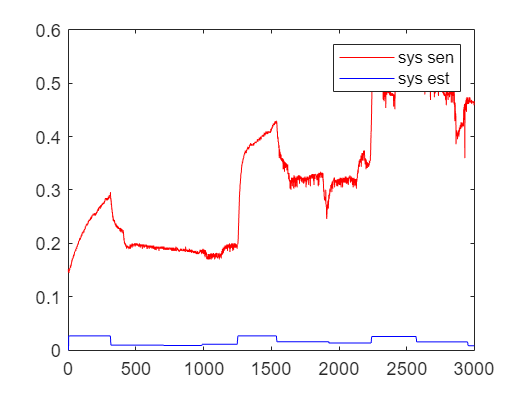

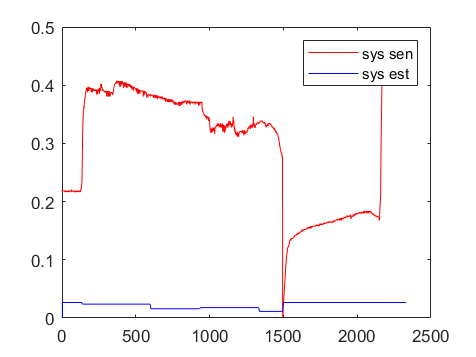

%ini yang awal
%
if style == 1
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_est1,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('sys sen','sys est','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');

figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
plot(tt,y_tes_est1,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('sys sen','sys est','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');

figure,
%step(sys), hold on
plot(tt,ys_step,'r'), hold on
plot(tt,y_step_est1,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('sys sen','sys est','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');

figure,
%impulse(sys), hold on
plot(tt,ys_imp,'r'), hold on
plot(tt,y_imp_est1,'b'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
legend('sys sen','sys est','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');

elseif style == 2
clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_est1,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('sys sen','sys est','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');

clear tt;
tt = (0:Ts:length(ys_tes)-1).';
figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
plot(tt,y_tes_est1,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('sys sen','sys est','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');

end

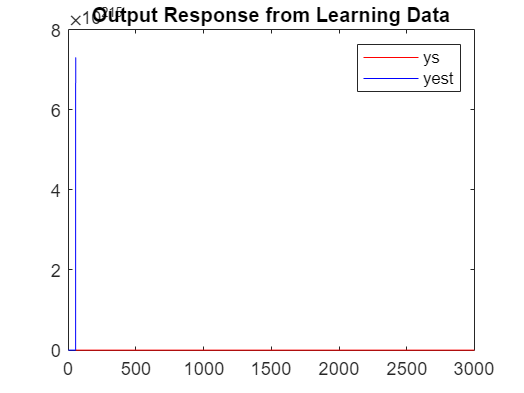

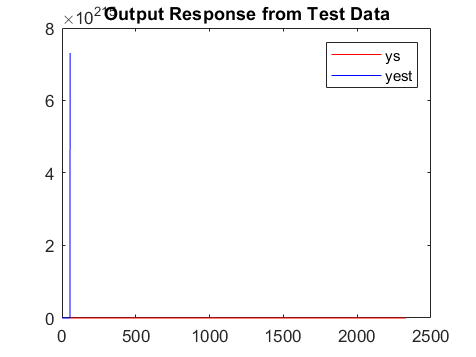

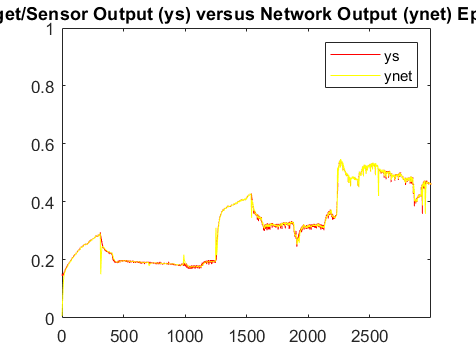

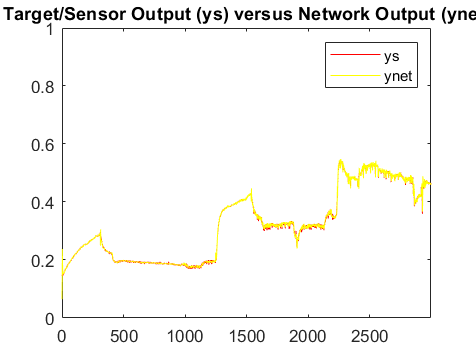

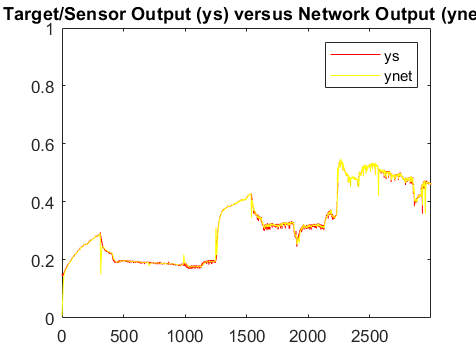

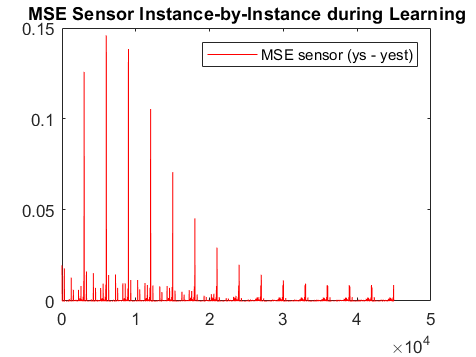

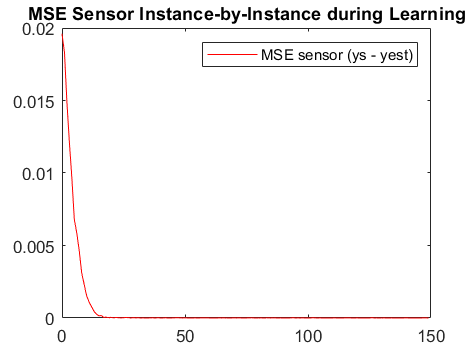

%ini yang terakhir
%
% figure,
% %step(sys), hold on
% plot(tt,y,'g'), hold on
% plot(tt,y_est,'b'), hold on
% %step(sys_est), hold on
% %step(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');
% 
% figure,
% %step(sys), hold on
% plot(tt,y_tes,'g'), hold on
% plot(tt,y_tes_est,'b'), hold on
% %step(sys_est), hold on
% %step(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');
% 
% figure,
% %step(sys), hold on
% plot(tt,y_step,'g'), hold on
% plot(tt,y_step_est,'b'), hold on
% %step(sys_est), hold on
% %step(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');
% 
% figure,
% %impulse(sys), hold on
% plot(tt,y_imp,'g'), hold on
% plot(tt,y_imp_est,'b'), hold on
% %impulse(sys_est), hold on
% %impulse(sys_lain)
% legend('sys','sys est','location','northeast');
% %legend('sys','sys est','sys lain','location','northeast');


if style == 1
%PAKAI SENSOR DENGAN MEASUREMENT NOISE
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Learning Data');

figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
plot(tt,y_tes,'g'), hold on
plot(tt,y_tes_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Test Data');

figure,
%step(sys), hold on
plot(tt,ys_step,'r'), hold on
plot(tt,y_step,'g'), hold on
plot(tt,y_step_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Step Response');

figure,
%impulse(sys), hold on
plot(tt,ys_imp,'r'), hold on
plot(tt,y_imp,'g'), hold on
plot(tt,y_imp_est,'b'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
legend('ys','y','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Impulse Response');


figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','y','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet) Epoch 1');

figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y,'g'), hold on
plot(tt,y_net_plot,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','y','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


for zz=1:size(mse_e,3)
    mse_e2((zz*size(mse_e,1)-size(mse_e,1)+1):(zz*size(mse_e,1)),:,:)=mse_e(:,:,zz);
end

ttt = 0:Ts:(size(mse_e2,1)-1);

figure,
plot(ttt,mse_e2,'g'), hold on
legend('MSE true (y - yest)','location','northeast');
title('MSE True Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_e2(1:150),'g'), hold on
legend('MSE true (y - yest)','location','northeast');
title('MSE True Instance-by-Instance during Learning');


%YANG TERHADAP BACAAN SENSOR
for zz=1:size(mse_es,3)
    mse_es2((zz*size(mse_es,1)-size(mse_es,1)+1):(zz*size(mse_es,1)),:,:)=mse_es(:,:,zz);
end

ttt = 0:Ts:(size(mse_es2,1)-1);

figure,
plot(ttt,mse_es2,'r'), hold on
legend('MSE sensor (ys - yest)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_es2(1:150),'r'), hold on
legend('MSE sensor (ys - yest)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');


elseif style == 2
%PAKAI SENSOR DENGAN MEASUREMENT NOISE
clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%step(sys), hold on
plot(tt,ys,'r'), hold on
%plot(tt,y,'g'), hold on
plot(tt,y_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
%legend('ys','y','yest','location','northeast');
legend('ys','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Learning Data');

clear tt;
tt = (0:Ts:length(ys_tes)-1).';
figure,
%step(sys), hold on
plot(tt,ys_tes,'r'), hold on
%plot(tt,y_tes,'g'), hold on
plot(tt,y_tes_est,'b'), hold on
%step(sys_est), hold on
%step(sys_lain)
%legend('ys','y','yest','location','northeast');
legend('ys','yest','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Output Response from Test Data');


clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet) Epoch 1');

clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


clear tt;
tt = (0:Ts:length(ys)-1).';
figure,
%impulse(sys), hold on
plot(tt,ys,'r'), hold on
plot(tt,y_net_plot0,'y'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
if style == 2 && jenis_data == 1 && limit == 1
ylim([0 1]);
end
xlim([tt(1) tt(size(tt,1))]);
legend('ys','ynet','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Target/Sensor Output (ys) versus Network Output (ynet)');


%YANG TERHADAP BACAAN SENSOR
for zz=1:size(mse_es,3)
    mse_es2((zz*size(mse_es,1)-size(mse_es,1)+1):(zz*size(mse_es,1)),:,:)=mse_es(:,:,zz);
end

ttt = 0:Ts:(size(mse_es2,1)-1);

figure,
plot(ttt,mse_es2,'r'), hold on
legend('MSE sensor (ys - yest)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

figure,
plot(ttt(1:150),mse_es2(1:150),'r'), hold on
legend('MSE sensor (ys - yest)','location','northeast');
title('MSE Sensor Instance-by-Instance during Learning');

end

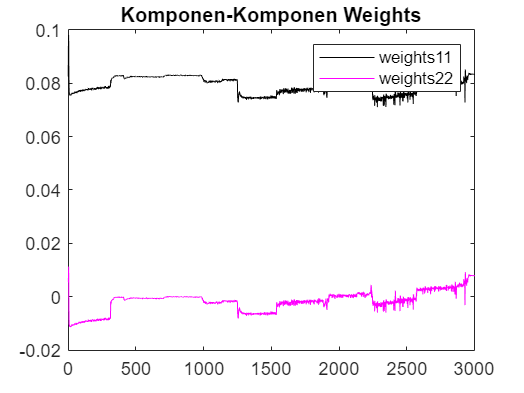

weights11_plot(:,:) = weights(1,1,:,epoch);
weights22_plot(:,:) = weights(2,2,:,epoch);
clear tt;
tt = (0:Ts:length(weights11_plot)-1).';
figure,
%impulse(sys), hold on
plot(tt,weights11_plot,'k'), hold on
plot(tt,weights22_plot,'m'), hold on
%impulse(sys_est), hold on
%impulse(sys_lain)
% if style == 2 && jenis_data == 1 && limit == 1
% ylim([0 1]);
% end
xlim([tt(1) tt(size(tt,1))]);
legend('weights11','weights22','location','northeast');
%legend('sys','sys est','sys lain','location','northeast');
title('Komponen-Komponen Weights');